# E11

#### Local Features: HoG

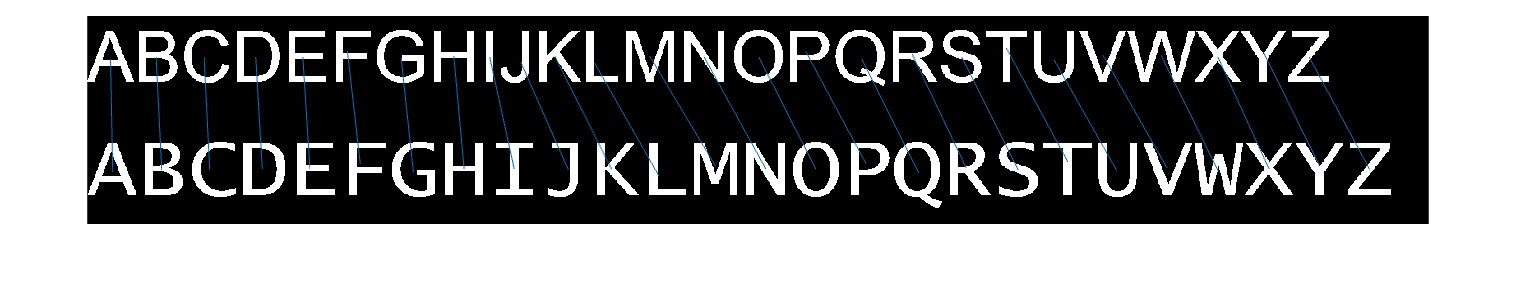

BW = rgb2gray(imread("Abecedari.png")) < 200;
imshow(BW);
% Objectiu: trobar quines lletres es corresponen
BWU = BW;
BWU(uint8(1:end/2), :) = 0;
%imshow(BWU);
BWD = BW;
BWD(uint8(end/2:end), :) = 0;
%imshow(BWD);

CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);

propsU = regionprops('table', CCU, 'Centroid');

propsD = regionprops('table', CCD, 'Centroid');

NumObj = CCU.NumObjects;

% Features
%FU = propsU.BoundingBox(:,3)./propsU.BoundingBox(:,4); % amplada/alçada
%FD = propsD.BoundingBox(:,3)./propsD.BoundingBox(:,4); % features
%FU = [propsU.EulerNumber];
%FD = [propsD.EulerNumber];
FU = extractHOGFeatures(BWU, propsU.Centroid, "CellSize", [16 16], "BlockSize", [3 3]);
FD = extractHOGFeatures(BWD, propsD.Centroid, "CellSize", [16 16], "BlockSize", [3 3]);

% normalitzem per columnes segons el seu valor maxim
% FU = FU./max(FU);
% FD = FD./max(FD);

A = zeros(NumObj, NumObj);
for i = 1: NumObj
    for j = 1: NumObj
        A(j,i) = norm(FU(i,:) - FD(j,:));
    end
end

costUnmatched = max(A, [], 'all');
Assig = matchpairs(A, costUnmatched);

%Assig = zeros([NumObj 1]);

% realitzem l'aparellament i eliminem els candidats aparellats
%for k = 1:NumObj
%    [Amins, idx] = min(A); % minims de cada columna i la fila
%    [Amins, Ai] = min(Amins);
%    Aj = idx(Ai);
%    Assig(Ai) = Aj;
%    A(Aj,:) = Inf;
%    A(:,Ai) = Inf;
%end

%Assig = dsearchn(FD, FU);

hold on
for i = 1:NumObj
    line([propsU.Centroid(i,1) propsD.Centroid(Assig(i),1)], [propsU.Centroid(i,2), propsD.Centroid(Assig(i),2)])
end
hold off

#### Harris Corner detection

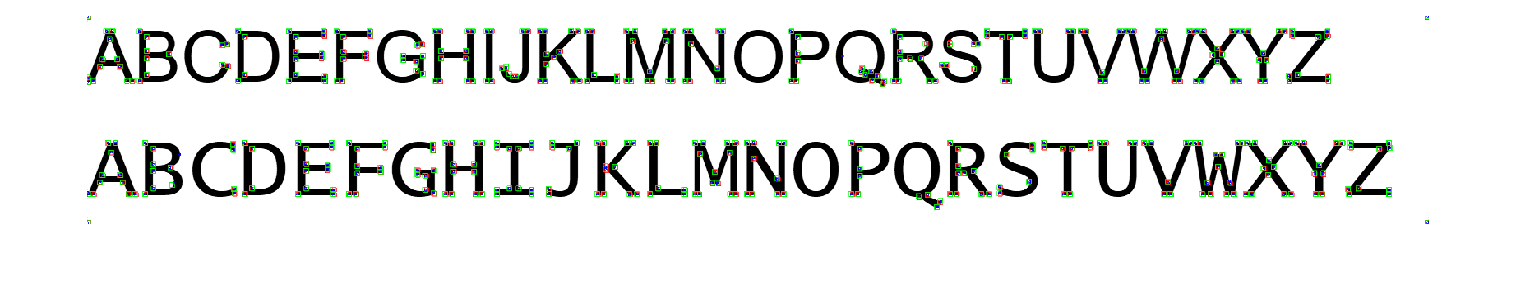

clearvars
im = rgb2gray(imread("Abecedari.png"));
imshow(im);
wsize = 5;
kp = Harris(double(im), wsize);
hold on
for i = 1:size(kp, 1)
    rectangle('Position', [kp.Centroid(i,1) - wsize/2, kp.Centroid(i,2) - wsize/2, wsize, wsize], 'EdgeColor', 'r');
end
wsize = 6;
kp = Harris(double(im), wsize);
for i = 1:size(kp, 1)
    rectangle('Position', [kp.Centroid(i,1) - wsize/2, kp.Centroid(i,2) - wsize/2, wsize, wsize], 'EdgeColor', 'g');
end
wsize = 10;
kp = Harris(double(im), wsize);
for i = 1:size(kp, 1)
    rectangle('Position', [kp.Centroid(i,1) - wsize/2, kp.Centroid(i,2) - wsize/2, wsize, wsize], 'EdgeColor', 'b');
end

#### Conclusions

En la imatge anterior, es poden veure els corners detectats amb una mida de finestra 5 de color vermell, de mida 6 de color verd i de mida 10 de color blau. Es pot apreciar que hi ha més corners detectats de blau, és a dir, la de finestra més gran,

Al augmentar el tamany de la finestra, es detecten més corners, ja que la finestra és més gran i és més susceptible de que hi hagi canvis en el contorn (corners a una escala més gran, pot no ser-ho en una escala petita). Per tant, no és invariant als canvis d'escala de la finestra. La conclusió que trec, és que l'escala de la finestra és un paràmetre que decideix l'usuari i es pren el valor que detecti més be els corners.

Fent zoom a la imatge, es poden apreciar corners que no observem sense fer zoom.

function [kp] = Harris(im, wsize)
    Sobel = [-1 0 1; -2 0 2; -1 0 1];
    %Sobel = fspecial("sobel");
    dx = imfilter(im, Sobel);
    dy = imfilter(im, Sobel');
    dx2 = dx .* dx;
    dy2 = dy .* dy;
    dxy = dx .* dy;

    s = fspecial("gaussian", wsize, wsize/4);

    Sumdx = imfilter(dx2, s);
    Sumdy = imfilter(dy2, s);
    Sumdxy = imfilter(dxy, s);
    
    R = (Sumdx .* Sumdy - (Sumdxy .* Sumdxy)) - 0.05 * (Sumdxy + Sumdxy).^2;
    
    T = mean(R, 'all') + 0.5 * std(R, [], 'all');

    RD = imdilate(R, ones(3,3));

    iR = (RD == R) & (R > T);
   
    kp = regionprops('table', iR, 'Centroid');
end
